% Exercise 3 
% Take input P and Q from user 
% Convert P and Q to complext variables  
% Determine the magnitude and angle 
% Convert to polar coordinate 

P = input('Enter the P value here: ');
Q = input('Enter the Q value here: ');
m_rec = complex(P,Q)

m_rec = 30.0000 +45.0000i

disp('The complex form is: ')

The complex form is: 


m_mag = abs(m_rec);
m_angle = angle(m_rec) * (180/pi);
m_polar = [m_mag, m_angle];
disp('The polar form [Magnitude Angle(Degree)]: ')

The polar form [Magnitude Angle(Degree)]: 


m_polar

m_polar =    54.0833   56.3099


% Considering another complex number n = 5 -i
A = 5;
B = 1;

n_rec = complex(A, B)

n_rec = 5.0000 + 1.0000i

O_rec = m_rec * n_rec

O_rec = 1.0500e+02 + 2.5500e+02i

function Ans = Euler_series(f, L, U, N, y1)
% Input parameters
% f: The function in differential equation
% L: Lower limit of X 
% U: Upper limit of X 
% N: Number of steps
% y1: Initial condition 
% Output parameters:
% Ans = [x, y]; y: ordinate

h = (U-L)/N;
y = zeros(N+1, 1);
x = zeros(N+1, 1);
x(1) = L;
y(1) = y1;

for i = 1:N
    y(i+1) = y(i) + h*f(x(i), y(i));
    x(i+1) = x(1) + i+h;
end

plot(x, y, '*');
grid on;
xlabel('x');
ylabel('y');
title('Differential equation: dy/dx = 5x^4+x^2-x+2y-14;7<=x<=20;y(0)=0.2');
Ans = [x,y];
end


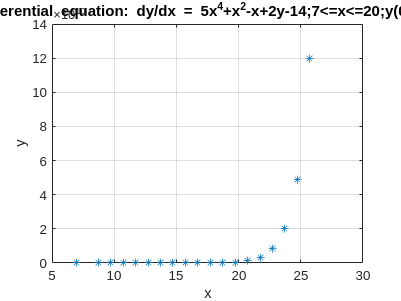

ans = 1.0e+11 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0001
    0.0000    0.0002
    0.0000    0.0004


clc; 

% Generate a function for the differential equation
% Differential equation: dy/dx = 2x^2+y-2 
% Condition 0 <= x <= 5; y(0) = 0.1
% N.B> Matlab iterate from 1, not from 0.
% Hence, for initial value y(0), we will consider it y(1).
% Number of step, N=18
% Number of steps, N=18

f = @(x,y) 5*x^4+x^2-x+2*y-14;
L = input('Enter the lower limit of x:');
U = input('Enter the upper limit of x:');
N = input('Enter the number of step:');
y1 = input('Enter initial value of y:');
Euler_series(f, L, U, N, y1)

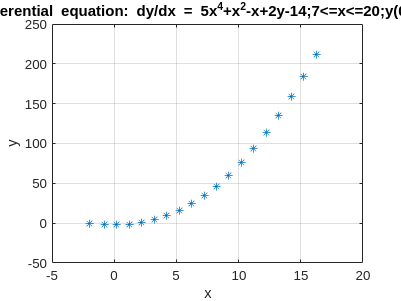

ans =    -2.0000    0.0500
   -0.7778   -1.2944
    0.2222   -1.7366
    1.2222   -1.0928
    2.2222    0.8401
    3.2222    4.2199
    4.2222    9.1697
    5.2222   15.7849
    6.2222   24.1400
    7.2222   34.2927


clc; 

% Generate a function for the differential equation
% Differential equation: dy/dx = 2x^2+y-2 
% Condition 0 <= x <= 5; y(0) = 0.1
% N.B> Matlab iterate from 1, not from 0.
% Hence, for initial value y(0), we will consider it y(1).
% Number of step, N=18
% Number of steps, N=18

f = @(x,y) x^2+5*x-y; 
L = input('Enter the lower limit of x:');
U = input('Enter the upper limit of x:');
N = input('Enter the number of step:');
y1 = input('Enter initial value of y:');
Euler_series(f, L, U, N, y1)